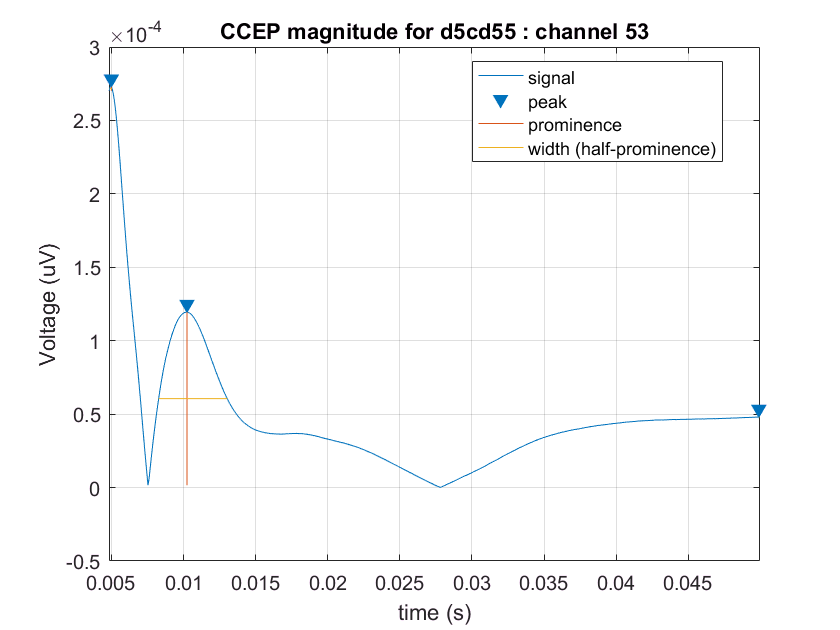

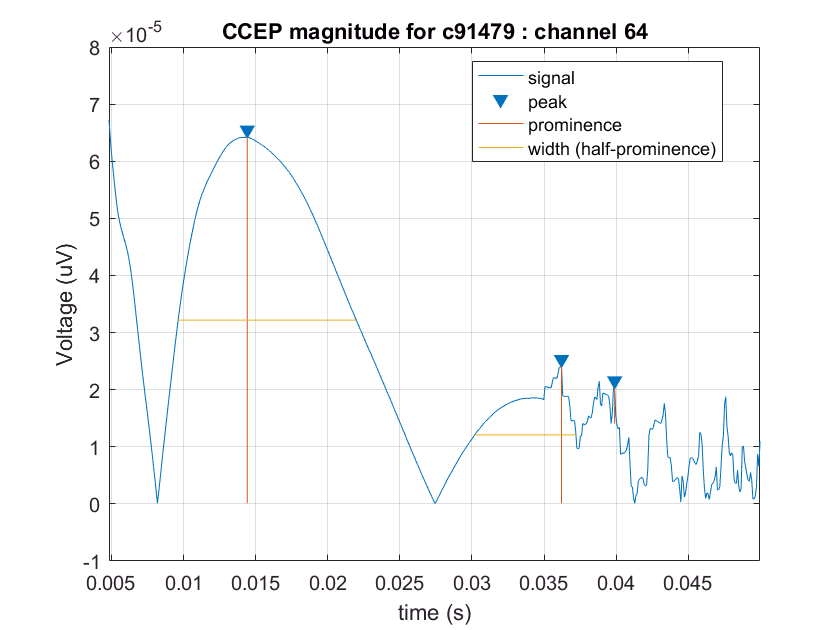

close all;clearvars; clc

Z_ConstantsLarryDavidStephen;

%sid = input('what is the SID?\n','s');


%%
for i = 2:length(SIDS)-2
    sid = SIDS{i};
    switch(sid)
        case 'd5cd55'
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            betaChan = 53;
            
        case 'c91479'
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
        case '7dbdec'
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            betaChan = 4;
            
        case '9ab7ab'
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            
        case '702d24'
            betaChan = 5;
            stims = [13 14];
            goods = [4 5 6 12 20 21 22];
            bads = [23 27 28 29 30 32];
            
        case 'ecb43e'
            betaChan = 55;
            stims = [56 64];
            goods = [55 63 54 46 47 48 46];
            
        case '0b5a2e'
            betaChan = 31;
            stims = [22 30];
                 goods = [12 13 14 15 16 21 23 31 32 39 40];
            % goods = [14 21 23 31];
            bads = [20 24 28];
            
        case '0b5a2ePlayback'
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            bads = [20 24 28];
    end
    
    load(fullfile(META_DIR, [sid '_StimulationAndCCEPs']));

    % look at electrode of interest .
    % for 0b5a2e it'll be 14 to start  , also look at 31 and 23
    
    % try setting t_new based off of how long the issues seem to be
    %t_min = 0.004833;
    t_min = 0.005
    t_max = 0.05;
    t_new = t(t>t_min & t < t_max);
    
    
    for chan = betaChan
        data = ECoGData((t>t_min & t<t_max),:,chan);
        data_mean  = mean(data,2);
        
        % average
        figure
       % [pks,locs,w,p]= findpeaks(abs(data_mean),t_new,'Annotate','extents','WidthReference','halfprom','MinPeakDistance',0.003,'sortstr','descend','minpeakheight',20e-6,'Npeaks',3)
       findpeaks(abs(data_mean),t_new,'Annotate','extents','WidthReference','halfprom','MinPeakDistance',0.003,'sortstr','descend','minpeakheight',20e-6,'Npeaks',3)
        xlabel('time (s)')
        ylabel('Voltage (uV)')
        title(['CCEP magnitude for ',sid,' : channel ',num2str(chan)])
    end
    
    clearvars -except SIDS i META_DIR OUTPUT_DIR
end      